### **Data extraciton**

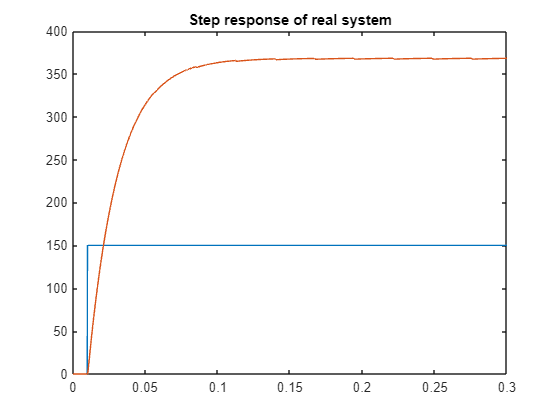

%Ts = 0.05;
Input_voltage_toAnalyse = Input_voltage_step.Data;
Output_speed_toAnalyse = Output_Speed.Data;

plot(tout,Input_voltage_toAnalyse);
title("Step response of real system");
xlim([0 0.3]);
ylim([0 400]);

hold on 
plot(tout,Output_speed_toAnalyse);

### **Transfer Function - 1st estimation**

sys = tf(Transfer_Function_T1)

sys =
 
  From input "u1" to output "y1":
    13.64 s + 4.443e05
  -----------------------
  s^2 + 3789 s + 1.812e05
 
Name: Transfer_Function_T1
Continuous-time transfer function.
Model Properties


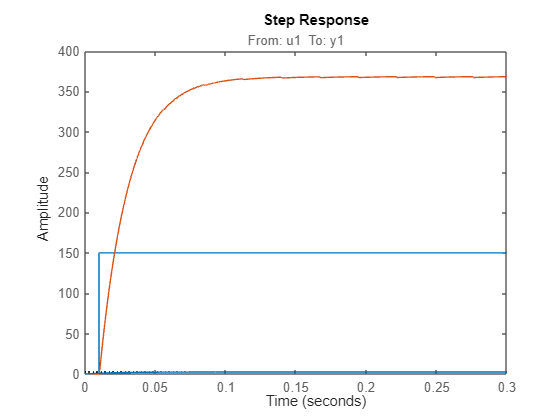

title("Step response of estimated Tf_1")
step(sys, 0.3)